clear;
rng(1)

train_input = [[-1;-1] [-0.75;-0.75] [-0.5;-0.5] [-0.25;-0.25] [0;0] [0.25;0.25] [0.5;0.5] [0.75;0.75] [1;1]];
train_targets = [0.1 0.3 0.5 0.7 0.9 1.1 1.3 1.5 1.7];
n_ex = numel(train_targets);        % number of training examples

%% He Weight Initialization
mu = 0;
gm1 = gmdistribution(mu, sqrt(2/2));
gm2 = gmdistribution(mu, sqrt(2/4));
gm3 = gmdistribution(mu, sqrt(2/2));

w1 = reshape(random(gm1, 8), [4 2]);
w2 = reshape(random(gm2, 8), [2 4]);
w3 = reshape(random(gm3, 2), [1 2]);

b1 = 0.1*ones([1 4]);
b2 = 0.1*ones([1 2]);
b3 = 0.1*ones([1 1]);

train = true;
alpha = 0.2;

for i = 1:500
    index = mod(i,n_ex)+1;
    input = train_input(:,index);
    target = train_targets(index);
    sim("ANN.slx");
    w1 = w1_out;
    w2 = w2_out;
    w3 = w3_out;
    b1 = b1_out;
    b2 = b2_out;
    b3 = b3_out;
end

train = false;
for i = 1:size(train_input, 2)
    input = train_input(:,i)
    sim("ANN.slx");
    output
    train_targets(i)
end

input =     -1
    -1


output =     0.1775

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 12

ans = 0.1000

input =    -0.7500
   -0.7500


output =     0.3374

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 12

ans = 0.3000

input =    -0.5000
   -0.5000


output =     0.4983

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 12

ans = 0.5000

input =    -0.2500
   -0.2500


output =     0.6873

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 12

ans = 0.7000

input =      0
     0


output =     0.8948

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 12

ans = 0.9000

input =     0.2500
    0.2500


output =     1.1016

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 12

ans = 1.1000

input =     0.5000
    0.5000


output =     1.3086

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 12

ans = 1.3000

input =     0.7500
    0.7500


output =     1.5161

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 12

ans = 1.5000

input =      1
     1


output =     1.7229

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 12

ans = 1.7000

N = 4;
D_in = 2;
H1 = 4;
H2 = 4;
D_out = 1;

x = [-0.5 -0.5; -0.1 0.1; 0.5 0.5; 0.8 0.8]';

y = [-0.5; 0.1; 0.5; 0.8];


w1 = randn(D_in, H1);
w2 = randn(H1, H2);
w3 = randn(H2, D_out);
prev_best_loss = realmax;

for i = 1:5000
    index = mod(i,numel(y)-1)+1;
    history_w1{i} = w1;
    history_w2{i} = w2;
    history_w3{i} = w3;

    [out_h1, w_h1, out_h2, w_h2, output] = forwardProp2(w1,w2,w3,x(:,index));
    
    history_outputs{i} = output;
    
    t1 = output - y;
    t2 = t1.^2;
    t3= sum(t2);
    losses(i) = t3;
    
    if losses(i) > 200
        w1 = randn(D_in, H1);
        w2 = randn(H1, H2);
        w3 = randn(H2, D_out);
        losses(i) = [];
        continue
    end
    
    if losses(i) < prev_best_loss
        best_w1 = w1;
        best_w2 = w2;
        best_w3 = w3;
        prev_best_loss = losses(i);
    end
    [w1, w2, w3] = back_pro_leakyReLu(x(:,index), out_h1, w_h1, out_h2, w_h2, output, w1, w2, w3, y(index));
end

[out_h1, w_h1, out_h2, w_h2, output] = forwardProp2(best_w1, best_w2, best_w3, [-0.5 -0.5]');
output

output = 0.1721

[out_h1, w_h1, out_h2, w_h2, output] = forwardProp2(best_w1, best_w2, best_w3, [-0.1 -0.1]');
output

output = 0.0344

[out_h1, w_h1, out_h2, w_h2, output] = forwardProp2(best_w1, best_w2, best_w3, [0.5 0.5]');
output

output = -0.5577

[out_h1, w_h1, out_h2, w_h2, output] = forwardProp2(best_w1, best_w2, best_w3, [0.8 0.8]');
output

output = -0.8923

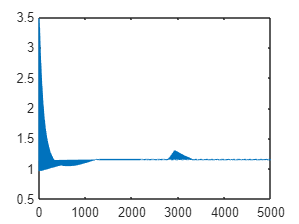


[out_h1, w_h1, out_h2, w_h2, test_output] = forwardProp2(best_w1,best_w2,best_w3,x);
plot(losses(1:1:end))

function [out_h1, w_h1, out_h2, w_h2, output] = forwardProp2(weights_1,weights_2, weights_3, input)
    %Feed-forward functionf for network with 2 layers
    
    out_h1 = weights_1' * input;
    w_h1 = out_h1;
    out_h1 = max(w_h1, 0);
    
    out_h2 = weights_2' * out_h1;
    w_h2 = out_h2;
    out_h2 = max(w_h2, 0);
    
    output = weights_3' * out_h2;
end

function [out_h1, w_h1, out_h2, w_h2, output] = forwardProp(weights_1,weights_2, weights_3, input)
    %Feed-forward functionf for network with 2 layers
    
    out_h1 = weights_1' * input;
    w_h1 = out_h1;
    for i = 1:30 
        if out_h1(i, 1) < 0 %leaky ReLU
            out_h1(i, 1) = 0.01*out_h1(i, 1);
        end
    end
    out_h2 = weights_2' * out_h1;
    w_h2 = out_h2;
    for i = 1:15
        if out_h2(i, 1) < 0 %leaky ReLU
            out_h2(i, 1) = 0.01*out_h2(i, 1);
        end
    end
    output = weights_3' * out_h2;
end

function [w1, w2, w3] = back_pro_leakyReLu(input, out_h1, w_h1, out_h2, w_h2, output, weights_1, weights_2, weights_3, target)
    learning_rate = 0.002;
    
    %output layer
    grad_output = (2.0 * (output - target))';
    grad_w3 =  out_h2 * grad_output;
    
    %hidden layer nr 2
    grad_h2_relu = grad_output * weights_3';
    grad_h2 = grad_h2_relu;
    grad_h2(w_h2 <= 0) = 0.0;
    grad_h2(w_h2 > 0) = 1;
    grad_w2 = out_h1 * grad_h2;

    %hidden layer nr 1
    grad_h1_relu = grad_h2 * weights_2';
    grad_h1 = grad_h1_relu;
    grad_h1(w_h1 <= 0) = 0.0;
    grad_h1(w_h1 > 0) = 1;
    grad_w1 = input * grad_h1;
    
    %updating the weights
    w1 = weights_1 - (learning_rate * grad_w1);
    w2 = weights_2 - (learning_rate * grad_w2);
    w3 = weights_3 - (learning_rate * grad_w3);
    
    
end

function weights = initializeWeights(inSize, outSize) %creates random weights based on the size given
  epsilon = 0.12;
  weights = rand(outSize, inSize) * 2 * epsilon - epsilon;
end